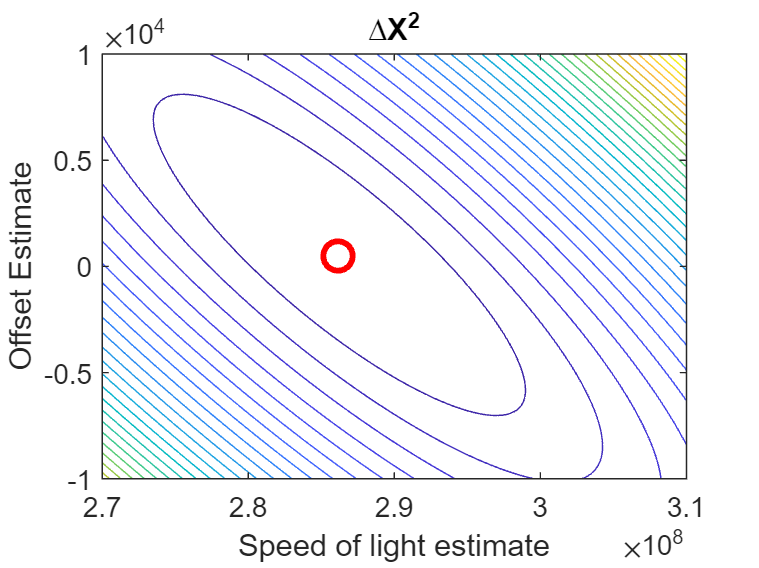

% Clear the workspace and close all open figures
clear;
clf;

% Load the data from the provided file
load('Speed_of_light_data.mat');

% Define the model function for fitting
modelfun = @(b, x) b(1) * x + b(2);

% Define a range of values for the slope (b1) and intercept (b2)
b1_range = linspace(2.7e8, 3.1e8, 100); % Adjust the range as needed
b2_range = linspace(-10000, 10000, 100);   % Adjust the range as needed

% Create a grid of b1 and b2 values
[B1, B2] = meshgrid(b1_range, b2_range);

% Initialize an array to store chi-squared values
chisq_values = zeros(size(B1));

% Calculate chi-squared values for different combinations of b1 and b2
for i = 1:numel(B1)
    test_distance = modelfun([B1(i), B2(i)], time);
    residuals = (test_distance - distance) ./ (error * ones(size(distance)));
    chisq_values(i) = sum(residuals.^2);
end

% Reshape chi-squared values to match the grid
chisq_values = reshape(chisq_values, size(B1));

% Create a contour plot of chi-squared values
figure;
contour(B1, B2, chisq_values, 30); % Adjust the number of contour levels as needed

% Add labels and a title
xlabel('Speed of light estimate');
ylabel('Offset Estimate');
title('∆X^2');

% Find the minimum chi-squared value and its corresponding parameters
[min_chisq, min_idx] = min(chisq_values(:));
[min_b1, min_b2] = ind2sub(size(chisq_values), min_idx);

% Overlay the minimum chi-squared point on the contour plot
hold on;
plot(B1(min_b1, min_b2), B2(min_b1, min_b2), 'ro', 'MarkerSize', 10, 'LineWidth', 2);
hold off;


% Display the minimum chi-squared point and its parameters
fprintf('Minimum Chi-Squared Value: %.4f\n', min_chisq);

Minimum Chi-Squared Value: 8.4849


fprintf('Best-Fit Slope (b1): %.4f\n', B1(min_b1, min_b2));

Best-Fit Slope (b1): 286161616.1616


fprintf('Best-Fit Intercept (b2): %.4f\n', B2(min_b1, min_b2));

Best-Fit Intercept (b2): 505.0505
